clc;
clear;
close all;

% Put all your CSV filenames here
files = {
    'Corner_Density_L_10_F_1.000.csv'
    'Corner_Density_L_10_F_1.500.csv'
    'Corner_Density_L_10_F_2.000.csv'
    'Corner_Density_L_10_F_2.500.csv'
    'Corner_Density_L_10_F_3.000.csv'
    'Corner_Density_L_10_F_3.500.csv'
    };

figure;
hold on;

% Loop through every file
for i = 1:length(files)

    fprintf('Reading file %d: %s\n', i, files{i});

    % Read CSV
    data = readmatrix(files{i});

    %fprintf('File read. Size: %d x %d\n', size(data,1), size(data,2));

    % Directly plot column 1 against column 2
    plot(data(:,2),data(:,1),LineWidth=0.5);

    %fprintf("Plot plotted");

    drawnow limitrate;

end

Reading file 1: Corner_Density_L_10_F_1.000.csv
Reading file 2: Corner_Density_L_10_F_1.500.csv
Reading file 3: Corner_Density_L_10_F_2.000.csv
Reading file 4: Corner_Density_L_10_F_2.500.csv
Reading file 5: Corner_Density_L_10_F_3.000.csv
Reading file 6: Corner_Density_L_10_F_3.500.csv


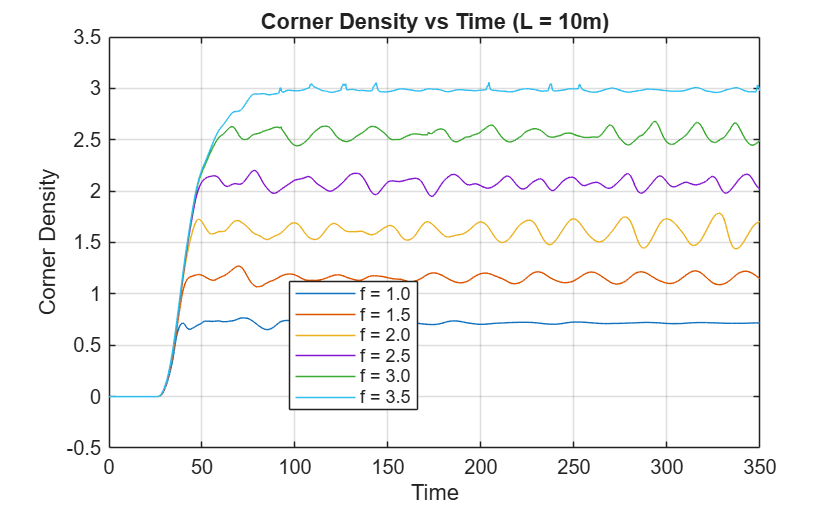


grid on;
box on;

xlabel('Time');
ylabel('Corner Density');
title('Corner Density vs Time (L = 10m)');

legend("f = 1.0", "f = 1.5", "f = 2.0", "f = 2.5", "f = 3.0", "f = 3.5", 'Interpreter', 'none', 'Location', 'best');

hold off;